# EE-414 Speech Processing Lab

#  Lab-10

## Introduction:

We know that speech sounds are categorized as voiced, unvoiced and silence sounds. The voiced speech is produced when input excitation is periodic in nature (when vocal folds of glottis vibrates periodically), the unvoiced speech is produced when input excitation is aperiodic (there is obstruction/constriction to the air flow) and silence is produced when the system is given no excitation.

There is pitch information associated with voiced sounds due to the periodicity (periodicity is assumed in short term processing), where the time period is known as pitch period and we can get pitch frequency (Fo or fundamental frequency) by taking the reciprocal of pitch period. This pitch frequency or simply pitch is useful for our analysis, for eg. it contains speaker specific information (might be helpful for speaker recognition), it is needed for speech coding, etc.

There are various methods to estimate pitch (some of which we have done in previous labs) such as :

- autocorrelation of speech signal. 

- cepstrum pitch determination

- simple inverse filtering technique

## Aim 

#### ● Develop a method for the estimation of pitch by the autocorrelation of speech signal. 

#### ● Develop a cepstrum pitch estimation method. 

#### ● Develop a simple inverse filtering technique(SIFT) pitch estimation method. 

#### ● Comparison of all these three methods. 

Spectrogram and Waveform of "Speech Signal" from wavesurfer

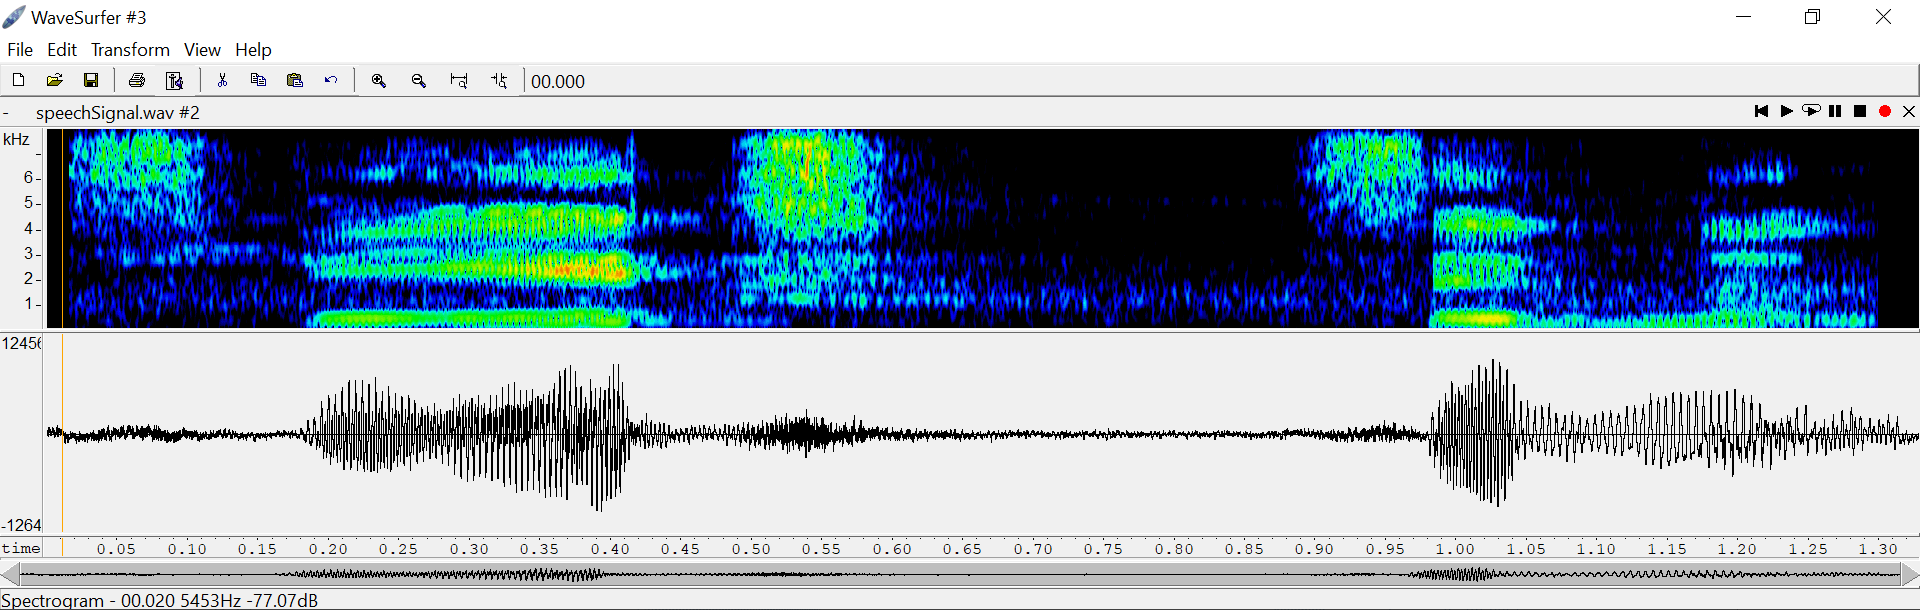

Record (16kHz, 16bit) the word “speech signal”; truncate long silence regions. 

### A. Pitch estimation by autocorrelation method: 

a. Divide the given speech signal into 30-40ms blocks of speech frames. Find and plot the auto-correlation sequence of a voiced frame and an unvoiced frame. 

b. Estimate the pitch frequency using this computed auto-correlation for the above voiced frame and an unvoiced frame. You may set a threshold for a significant peak, and assign zero to pitch frequency if there is no significant peak.

#### Theory:

We can get the "To" easily by computing the autocorrelation of the voiced sound. The second largest peak signifies the 'To' (the time lag between 1st and 2nd peak) and hence we can estimate the pitch frequency easily. The peak can be found by a simple peak-picking algorithm.

#### Procedure:

We get the sound sample and plot time signal. Then we take the voiced and unvoiced part and take a small frame of 30ms at the centre of these sounds and apply hamming window. We then compute the ACF and plot it, and then find 2nd largest peak by a peak-picking algorithm. The corresponding time of this peak signifies the time period and hence we can calculate pitch frequency by simply taking the reciprocal of it.

#### **Code:**

**a.**

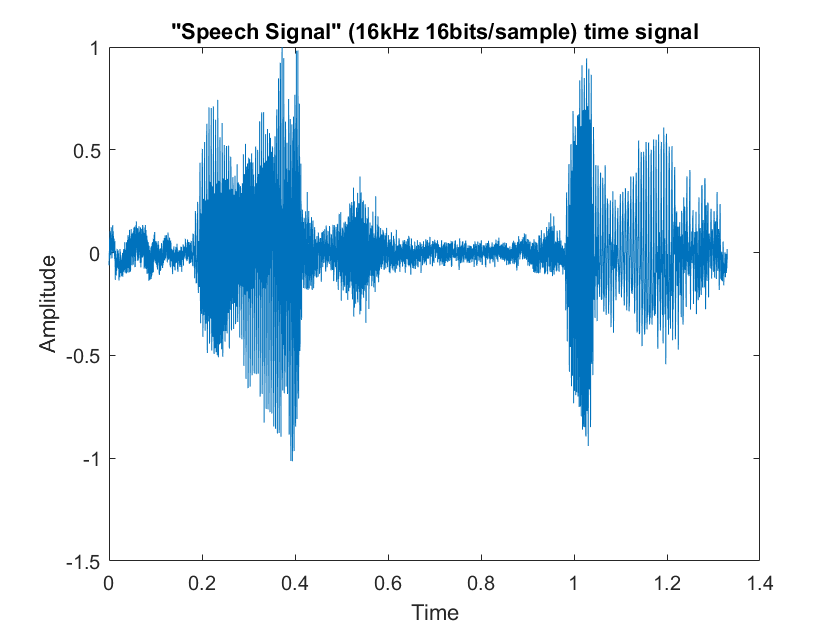

close all; clc; clear all;

[y,fs]=audioread('speechSignal.wav'); 

sound_sample = y(:,1); % Taking left channel
sound_sample = sound_sample./max(sound_sample); % Normalizing

% "Speech Signal" 
plot_time_signal(sound_sample, fs, '"Speech Signal" (16kHz 16bits/sample) time signal'); 

**Voiced**

voiced_part = sound_sample(round(0.30*fs):round(0.40*fs)); % ee 

size = 0.030; % frame size = 30ms

% Taking a frame size at centre of sound and windowing
voiced_frame = voiced_part(round(length(voiced_part)/2) - (size/2)*fs:round(length(voiced_part)/2) + (size/2)*fs - 1);
win = dsp.Window("Hamming");
voiced_hamm = win(voiced_frame);

% plotting for voiced frame
subplot(221)
plot_time_signal(voiced_hamm, fs, 'voiced frame waveform "ee" ');

% plotting ACF 
ACF_Voiced = autocorr(length(voiced_hamm), voiced_hamm);
subplot(223)
plot(ACF_Voiced);
title('ACF for "voiced frame"');
xlabel('k (delay)');
ylabel('ACF');

**Unvoiced**

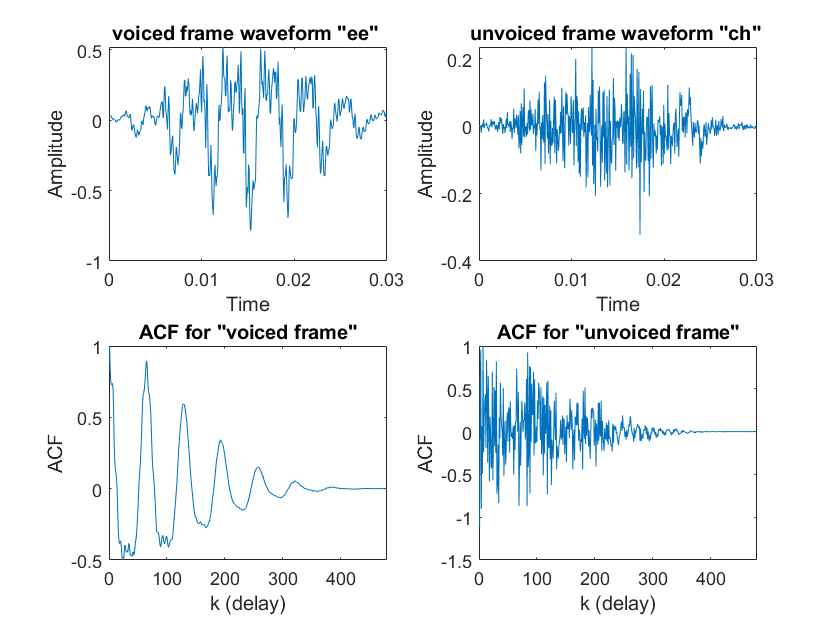

unvoiced_part = sound_sample(round(0.5*fs):round(0.6*fs)); % ch 

size = 0.030; % frame size = 30ms

% Taking a frame size at centre of sound and windowing
unvoiced_frame = unvoiced_part(round(length(unvoiced_part)/2) - (size/2)*fs:round(length(unvoiced_part)/2) + (size/2)*fs - 1);
win = dsp.Window("Hamming");
unvoiced_hamm = win(unvoiced_frame);

% plotting for unvoiced frame
subplot(222)
plot_time_signal(unvoiced_hamm, fs, 'unvoiced frame waveform "ch" ');

% plotting ACF
ACF_Unvoiced = autocorr(length(unvoiced_hamm), unvoiced_hamm);
subplot(224)
plot(ACF_Unvoiced);
title('ACF for "unvoiced frame"');
xlabel('k (delay)');
ylabel('ACF');

#### **b.**

**Voiced**

close hidden;

[pks,locs] = findpeaks(ACF_Voiced, 'MinPeakDistance',20);
[~, index] = max(pks);

n = (0:length(ACF_Voiced)-1)/fs;
subplot(211);
plot(n, ACF_Voiced, n(locs(index)), pks(index),'r*');
title('ACF for "voiced frame"'); xlabel('seconds (delay)');ylabel('ACF');

pitch_pd = locs(index);
pitch_f = (1/pitch_pd)*fs;
fprintf("Pitch Frequency for voiced: %.3f Hz", pitch_f);

Pitch Frequency for voiced: 246.154 Hz

**Unvoiced**

[pks,locs] = findpeaks(ACF_Unvoiced, 'MinPeakDistance',20);
[~, index] = max(pks);
pitch_pd = locs(index);
pitch_f = (1/pitch_pd)*fs;
fprintf("Pitch Frequency for unvoiced: %.3f Hz", pitch_f);

Pitch Frequency for unvoiced: 2285.714 Hz

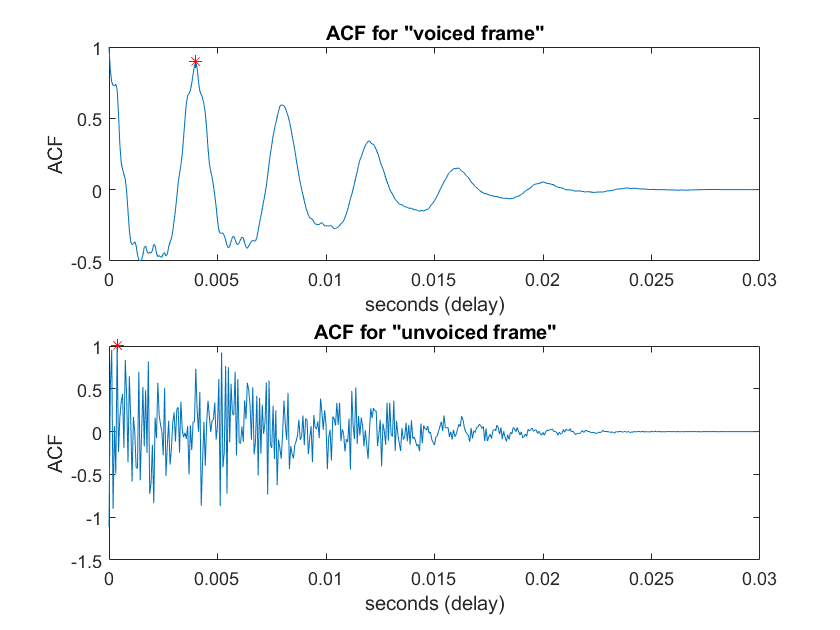

n = (0:length(ACF_Unvoiced)-1)/fs;
subplot(212)
plot(n, ACF_Unvoiced, n(locs(index)), pks(index),'r*');
title('ACF for "unvoiced frame"'); xlabel('seconds (delay)');ylabel('ACF');

#### **Observations:**

We can see there are significant peaks in voiced sound whereas that is not the case with unvoiced sound. We are not able to see significant peaks, rather there are many peaks of which none are significant enough to be considered. We find the pitch frequency to be 250 Hz by using ACF method.

### B. Cepstrum based pitch estimation: 

a. Divide the speech into short segments of 15-20ms frame size. Compute the cepstrum of the speech segment in the quefrency domain for each of these frames and plot for one voiced frame. 

b. Estimate the pitch period by the high time liftering of the cepstrum of the voiced speech. 

c. Estimate the pitch period by the high time liftering of the cepstrum of the unvoiced speech. 

#### Theory:

ACF method has some limitations, i.e. there might be peaks that are larger than the peak corresponding to the time period. This causes incorrect estimation of the pitch. In cepstral analysis, we can get vocal tract information and excitation source separately. By high time liftering of the cepstrum, we can get the excitation source information, and then we can get a better estimation of the pitch as pitch is an inherent property coming from the excitation source information. The excitation source is fast varying hence we can apply high time liftering to get this information, whereas vocal tract information is slow varying (hence we should do low time liftering).

#### Procedure:

We take a small voiced and unvoiced frame of 20 ms and apply hamming window. We then compute the cepstrum and apply high time liftering to get the excitation source info. We get the time duration corresponding to the prominent peak and that will be our 'To', and hence we can calculate the pitch frequency.

#### **Code:**

**a.**

**Voiced**

close hidden
% getting s_n
voiced_part = sound_sample(round(0.30*fs):round(0.40*fs)); % ee 
voiced_frame = voiced_part(round(length(voiced_part)/2) - 0.010*fs:round(length(voiced_part)/2) + 0.010*fs - 1); % 20ms frame size

% getting x_n by windowing
win = dsp.Window("Hamming");
voiced_hamm = win(voiced_frame);

% plotting for voiced frame
subplot(321)
plot_time_signal(voiced_hamm, fs, 'voiced frame waveform "ee" ');
subplot(323)
plot_freq_spectrum(voiced_hamm, fs, 'Log Magnitude spectrum of voiced frame "ee"', 'log');

% getting c_n i.e. cepstrum 
cepst_voiced = ifft(log(abs(fftshift(fft(voiced_hamm)))));
cepst_voiced = cepst_voiced(1:round(length(cepst_voiced)/2));

% plotting cepstrum
subplot(325)
plot(cepst_voiced);
title('cepstrum of voiced frame "ee"'); xlabel('quefrency/samples'); ylabel('amplitude');

**Unvoiced**

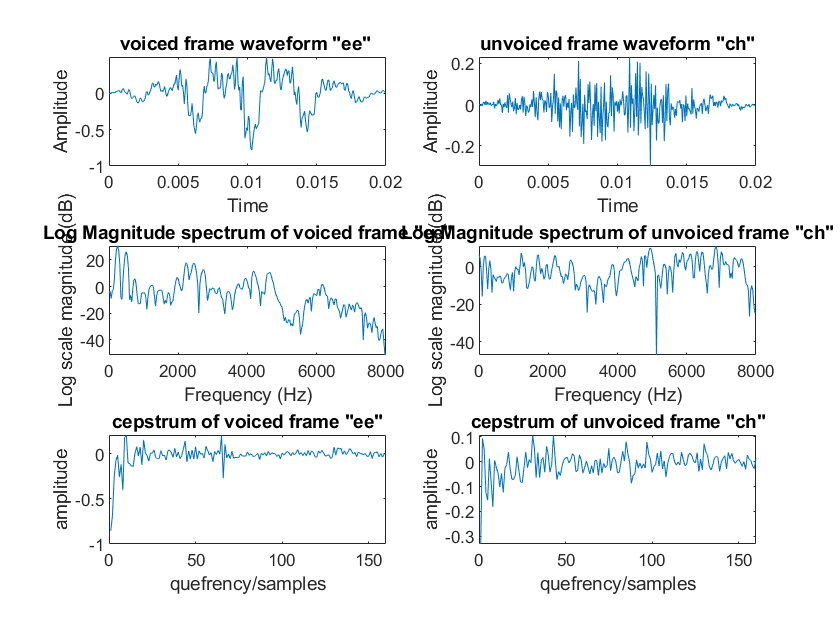

% getting s_n
unvoiced_part = sound_sample(round(0.5*fs):round(0.6*fs)); % ch
unvoiced_frame = unvoiced_part(round(length(unvoiced_part)/2 - 0.010*fs):round(length(unvoiced_part)/2 + 0.010*fs)-1);

% getting x_n by windowing
win = dsp.Window("Hamming");
unvoiced_hamm = win(unvoiced_frame);

% plotting for unvoiced frame
subplot(322)
plot_time_signal(unvoiced_hamm, fs, 'unvoiced frame waveform "ch"');
subplot(324)
plot_freq_spectrum(unvoiced_hamm, fs, 'Log Magnitude spectrum of unvoiced frame "ch"', 'log');

% getting c_n i.e. cepstrum 
cepst_unvoiced = ifft(log(abs(fftshift(fft(unvoiced_hamm)))));
cepst_unvoiced = cepst_unvoiced(1:round(length(cepst_unvoiced)/2));

% plotting cepstrum
subplot(326)
plot(cepst_unvoiced);
title('cepstrum of unvoiced frame "ch"'); xlabel('quefrency/samples'); ylabel('amplitude');

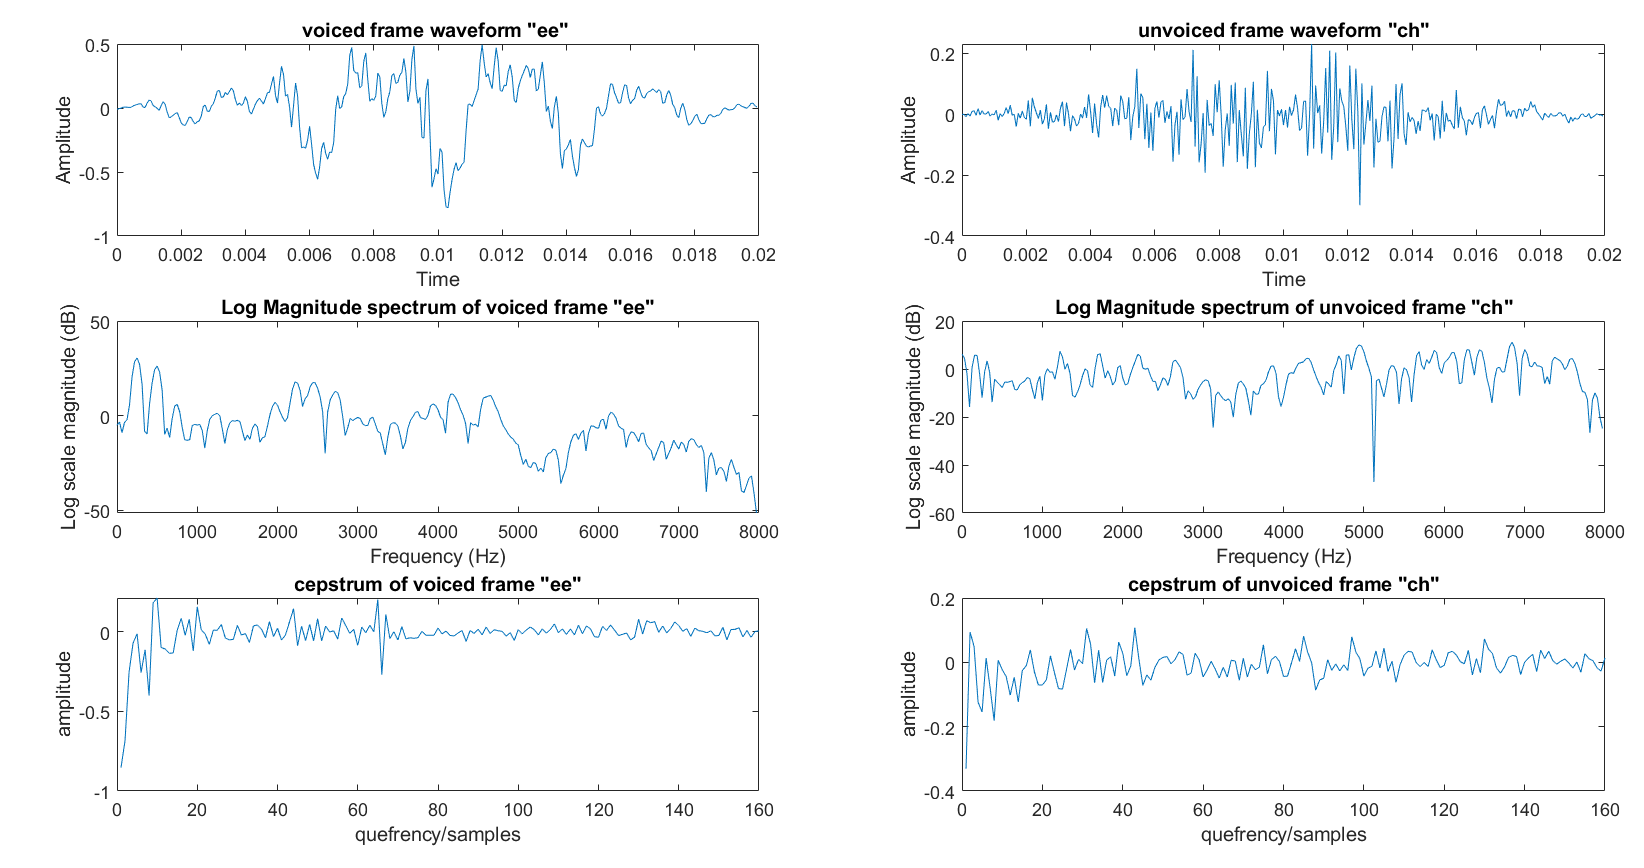

**b.**

**Voiced**

% creating high pass filter
close hidden;
Lc = 15;
w_2 = zeros(1,length(cepst_voiced));
w_2(Lc:length(cepst_voiced)) = 1;

% high pass liftering
high_liftered_voiced = cepst_voiced.*w_2';

% pitch estimation
xIndex = find(high_liftered_voiced == max(high_liftered_voiced), 1, 'first');

subplot(211)
plot(high_liftered_voiced);
hold on
plot(xIndex, high_liftered_voiced(xIndex), 'r*');
title('cepstrum of high liftered voiced sound "ee"'); xlabel('quefrency/samples'); ylabel('amplitude');

pitch_pd = xIndex/fs;
pitch_f = (1/pitch_pd);

fprintf("Pitch Frequency for voiced: %.3f Hz", pitch_f);

Pitch Frequency for voiced: 246.154 Hz

**Unvoiced**

% creating high pass filter
w_2 = zeros(1,length(cepst_unvoiced));
w_2(Lc:length(cepst_unvoiced)) = 1;

% high pass liftering
high_liftered_unvoiced = cepst_unvoiced.*w_2';

  
% pitch estimation
xIndex = find(high_liftered_unvoiced == max(high_liftered_unvoiced), 1, 'first');

pitch_pd = xIndex/fs;
pitch_f = (1/pitch_pd);

fprintf("Pitch Frequency for unvoiced: %.3f Hz", pitch_f);

Pitch Frequency for unvoiced: 372.093 Hz

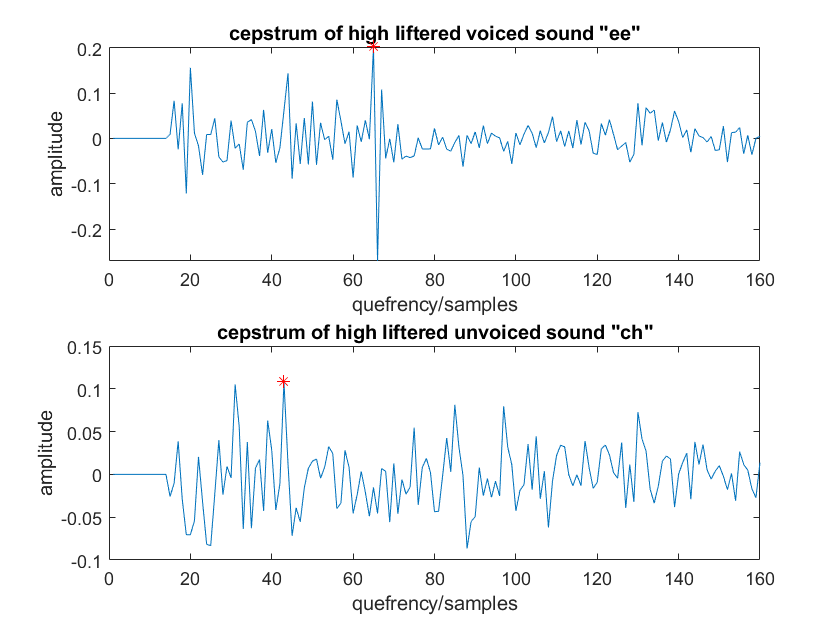

subplot(212)
plot(high_liftered_unvoiced);
hold on
plot(xIndex, high_liftered_unvoiced(xIndex), 'r*');
title('cepstrum of high liftered unvoiced sound "ch"'); xlabel('quefrency/samples'); ylabel('amplitude');

#### Observations:

We see that there is a significant/prominent peak in the high liftered cepstrum for the voiced sound whereas we cannot see a prominent peak in the unvoiced sound. We get pitch frequency of the  voiced sound as 246.154 Hz.

### C. Pitch estimation by Simple Inverse Filtering Technique (SIFT):

a. Take a 30 ms voiced speech segment and compute the Linear Prediction (LP) residual by LP analysis. Perform autocorrelation on the LP residual. Estimate of pitch period from the autocorrelation sequence of the LP residual. 

b. Perform the same for the unvoiced speech segment also.

#### Theory:

By LP analysis, we can separate the vocal tract information and excitation source information, and hence we can estimate the pitch more correctly. The residual signal signifies the excitation source information. The periodicity of the error (LP residual is an error signal) gives the pitch period of that speech segment and this can be computed by the autocorrelation method. 

#### Procedure:

We take a 30ms segment of voiced/unvoiced sound and find the LP coefficients corresponding to this. We then compute the residual signal by convolution of the voiced segment with these LP coefficients. We then compute the ACF of this residual signal and then the pitch period can be found as the time difference between the highest peak and the next highest peak of the auto correlation function.

#### Code:

close hidden
ACF = autocorr(length(voiced_hamm), voiced_hamm);
P = 13; % Order

R = ACF(1:P); % R(0) to R(P-1)
r = (ACF(2:(P+1)))'; % R(1) to R(P)

R = toeplitz(R); % writing in form of toeplitz matrix
L_coeffs = -(inv(R))*(r);

LP_residual = conv(voiced_hamm, L_coeffs);

subplot(221)
plot_time_signal(LP_residual, fs, 'Residual signal of voiced frame waveform "ee" ');
ACF_LP = autocorr(length(LP_residual), LP_residual);


[pks,locs] = findpeaks(ACF_LP, 'MinPeakDistance',20);
[~, index] = max(pks);

n = (0:length(ACF_LP)-1)/fs;
subplot(223)
plot(n, ACF_LP, n(locs(index)), pks(index),'r*');
title('ACF for Residual signal of "unvoiced frame"');
xlabel('k (delay)');
ylabel('ACF');
pitch_pd = locs(index);
pitch_f = (1/pitch_pd)*fs;
fprintf("Pitch Frequency: %.3f Hz", pitch_f);

Pitch Frequency: 246.154 Hz

**Unvoiced**

ACF = autocorr(length(unvoiced_hamm), unvoiced_hamm);
P = 13; % Order

R = ACF(1:P); % R(0) to R(P-1)
r = (ACF(2:(P+1)))'; % R(1) to R(P)

R = toeplitz(R); % writing in form of toeplitz matrix
L_coeffs = -(inv(R))*(r);

LP_residual = conv(unvoiced_hamm, L_coeffs);

subplot(222)
plot_time_signal(LP_residual, fs, 'Residual signal of unvoiced frame waveform "ee" ');
ACF_LP = autocorr(length(LP_residual), LP_residual);
[pks,locs] = findpeaks(ACF_LP, 'MinPeakDistance',20);
[val, index] = max(pks);

pitch_pd = locs(index);

pitch_f = (1/pitch_pd)*fs;
fprintf("Pitch Frequency: %.3f Hz", pitch_f);

Pitch Frequency: 2285.714 Hz

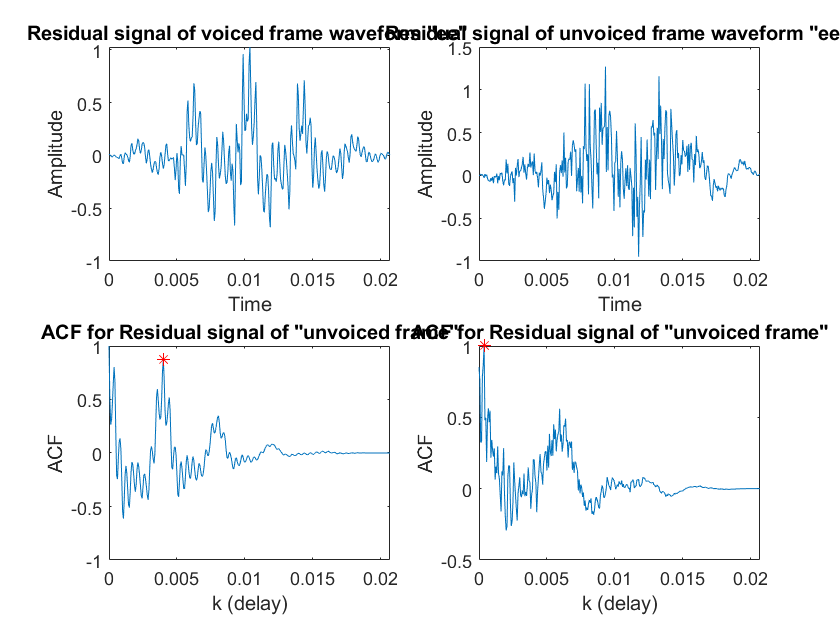

n = (0:length(ACF_LP)-1)/fs;
subplot(224);
plot(n, ACF_LP, n(locs(index)), pks(index),'r*');
title('ACF for Residual signal of "unvoiced frame"');
xlabel('k (delay)');
ylabel('ACF');

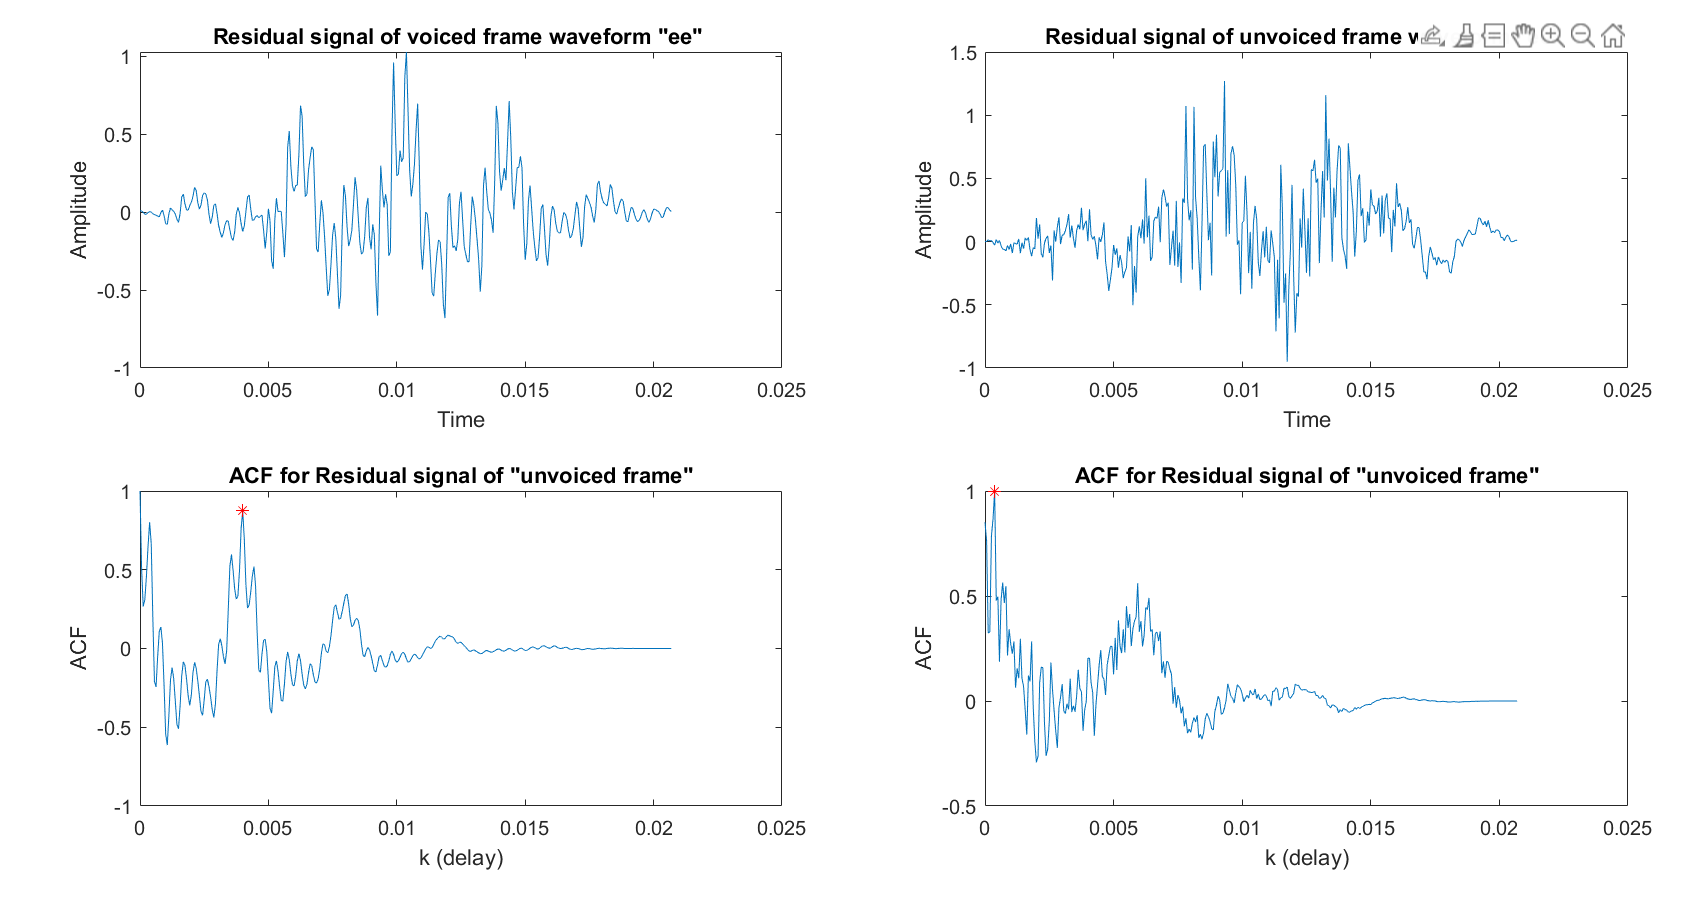

#### **Observations:**

We see prominent peaks in the ACF for voiced sounds. We get pitch frequency as 246.154 Hz for voiced sounds, which is matching the pitch frequency we estimated from cepstral analysis. 

### D. Comparison of pitch estimation methods:

a. Plot the entire input speech signal and it’s pitch contours estimated using autocorrelation, cepstrum and SIFT based pitch estimation methods.

#### Theory:

We can see that the cepstral and LP analysis method of estimating the pitch is much better than simply taking ACF of the sound, as these focus on the excitation source information and pitch estimation is much better. In speech coding, SIFT is used whereas in speaker recognition, cepstrum pitch estimation is usually used.

#### Procedure:

We plot the entire speech signal, and then divide the signal into frames and compute the pitch using the 3 methods for each of these frames and plot the pitch frequency for each frame. We then plot these pitch contours and make relevant observations.

#### Code

#### b)

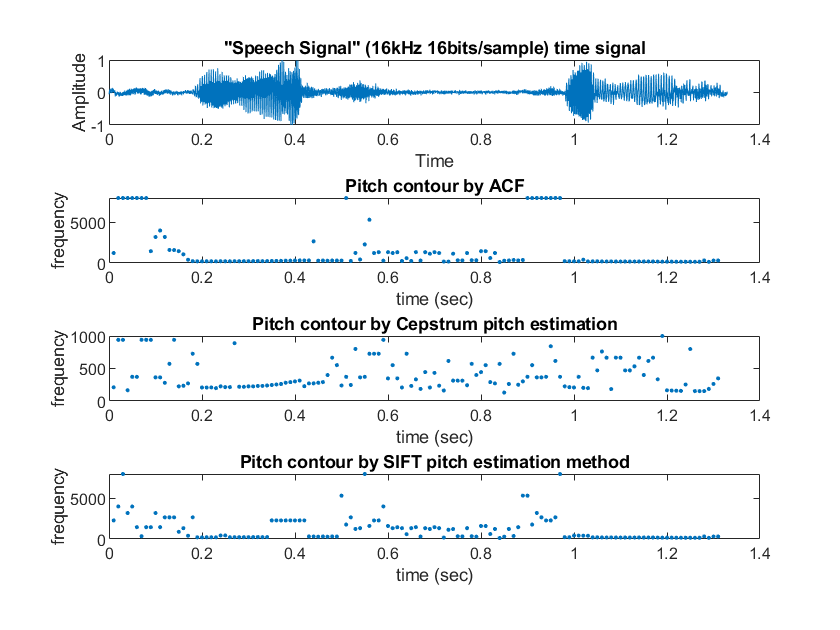

close hidden
subplot(411)
plot_time_signal(sound_sample, fs, '"Speech Signal" (16kHz 16bits/sample) time signal'); 

frame_size = 0.025;
frame_shift = 0.010;

no_of_frames = length(0:frame_shift:length(sound_sample)/fs-frame_size);

pitches_ACF = [];
pitches_Cep = [];
pitches_SIFT = [];

n = 0;

for j = 1:no_of_frames
    s = sound_sample((1+round((n*frame_shift)*fs)):(round((n*frame_shift + frame_size)*fs)));
    win = dsp.Window("Hamming");
    x = win(s);
    
    % ******* ACF *******
    ACF = autocorr(length(x), x);

    [pks,locs] = findpeaks(ACF, 'MinPeakDistance',20);
    [~, index] = max(pks);
    pitch_pd = locs(index);
    pitch_f = (1/pitch_pd)*fs;
    
    pitches_ACF = [pitches_ACF pitch_f];
    
    % ******* Cepstral pitch estimation *******
    % getting c_n i.e. cepstrum 
    cepst= ifft(log(abs(fftshift(fft(x)))));
    cepst= cepst(1:round(length(cepst)/2));
    
    % creating high time lifter
    Lc = 15;
    w_2 = zeros(1,length(cepst));
    w_2(Lc:length(cepst)) = 1;
    
    % high pass liftering
    high_liftered= cepst.*w_2';
    
    % pitch estimation
    xIndex = find(high_liftered== max(high_liftered), 1, 'first');
    pitch_pd = xIndex/fs;
    pitch_f = (1/pitch_pd);
    pitches_Cep= [pitches_Cep pitch_f];
    
    % ******* SIFT estimation *******
    P = 13; % Order
    
    R = ACF(1:P); % R(0) to R(P-1)
    r = (ACF(2:(P+1)))'; % R(1) to R(P)
    
    R = toeplitz(R); % writing in form of toeplitz matrix
    L_coeffs = -(inv(R))*(r);
    
    LP_residual = conv(x, L_coeffs);
    ACF_LP = autocorr(length(LP_residual), LP_residual);
    
    [pks,locs] = findpeaks(ACF_LP, 'MinPeakDistance',20);
    [~, index] = max(pks);
    pitch_pd = locs(index);
    pitch_f = (1/pitch_pd)*fs;
    
    pitches_SIFT= [pitches_SIFT pitch_f];
    
    n = n+1;
end

subplot(412)
plot((1:no_of_frames)*0.01, pitches_ACF, '.');
title('Pitch contour by ACF'); xlabel('time (sec)'); ylabel('frequency');
subplot(413)
plot((1:no_of_frames)*0.01, pitches_Cep, '.');
title('Pitch contour by Cepstrum pitch estimation'); xlabel('time (sec)'); ylabel('frequency');
subplot(414)
plot((1:no_of_frames)*0.01, pitches_SIFT, '.');
title('Pitch contour by SIFT pitch estimation method'); xlabel('time (sec)'); ylabel('frequency');

#### 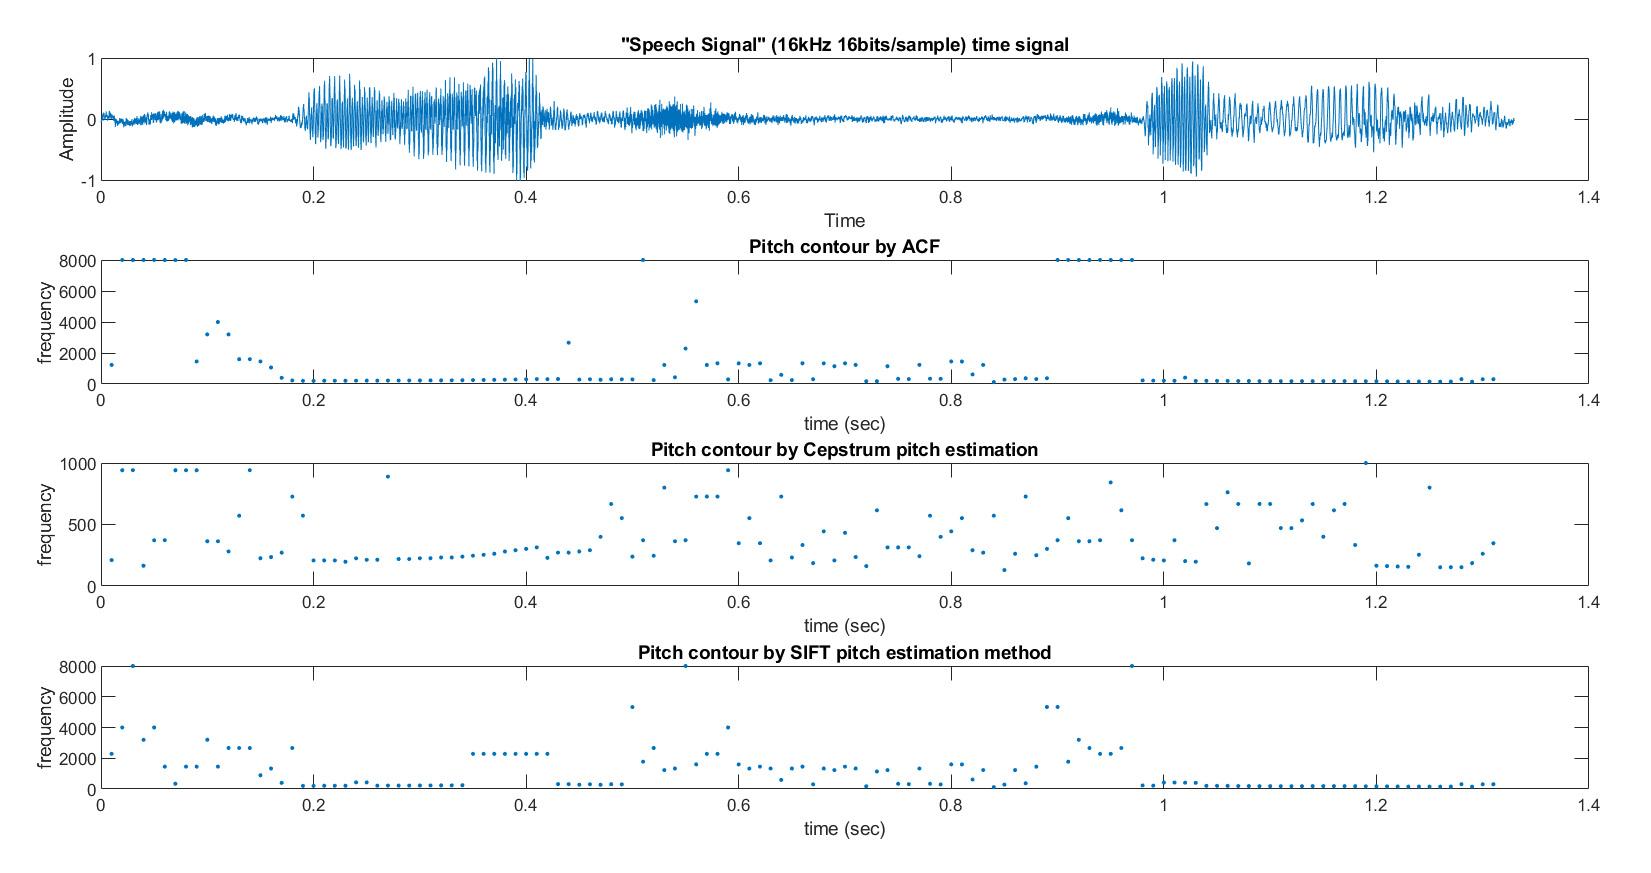

#### Observations:

We see that for voiced regions, we see a smooth (somewhat continuous) segment whereas for unvoiced/silence regions the pitch contours are either random or they have very high value or both.

### Function Definitions

function plot_time_signal(y, fs, title_name)  % PLOT TIME DOMAIN PLOT FOR ANY SIGNAL
    plot((0:length(y)-1)/fs,y);
    xlabel("Time");
    ylabel("Amplitude");
    title(title_name);
end

function plot_freq_spectrum(x, fs, title_name, mode)
    N = length(x);
    n = pow2(nextpow2(N)); % Transforming the length so that the number of samples is a power of 2. 
    f = fs*[0: n-1]/n;
    if strcmp(mode, 'linear')
        X_mags = (abs(fft(x, n)));
        X_mags = X_mags/n;
        y_label = 'Linear scale magnitude';
    elseif  strcmp(mode, 'log')
        X_mags = 20*log10(abs(fft(x, n)));
        y_label = 'Log scale magnitude (dB)';
    end
    N_2 = ceil(n/2);
    plot(f(1:N_2), (X_mags(1:N_2)));
    xlabel('Frequency (Hz)')
    ylabel(y_label);
    title(title_name);
end

% CALCULATING AUTO CORRELATION FUNCTION
function ACF = autocorr(no_of_samples, signal)
    N = no_of_samples;
    ACF = [];
    for i = 1:N 
        sum = 0;
        for j = 1:N-i
            sum = sum + signal(j)*signal(j+i);
        end
        ACF = [ACF sum];
    end
    ACF = ACF./max(ACF);
end
